### 1. Loading and exploring image dataset

(for simplicity purporses I have previously preprocessed the images in Python (CYMK to RBG, reshaping to 64x64) to match Matlab's requirements)

data_folder = "";
imds = imageDatastore(data_folder, ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames"); % folder names as classes' labels

Example images from dataset:

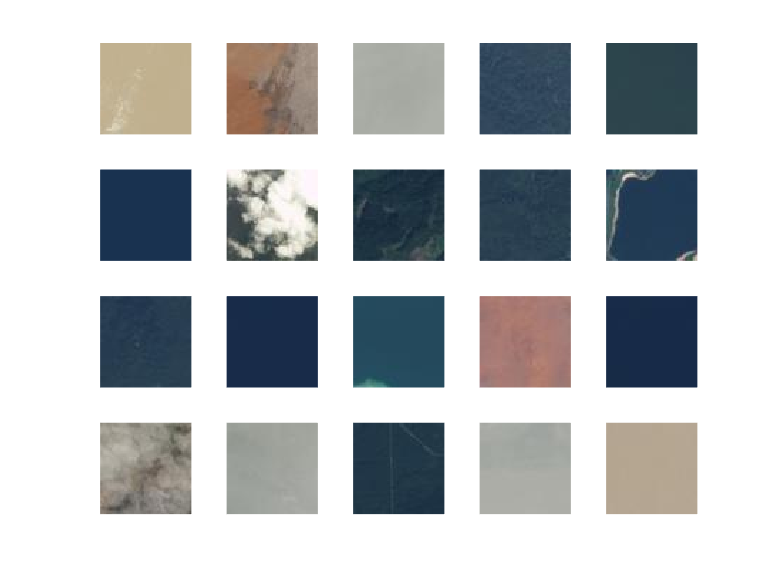

figure
tiledlayout("flow");
perm = randperm(5631,20);
for i = 1:20 % display random 20 images 
    nexttile
    imshow(imds.Files{perm(i)});
end

Checking count of files for each label

classNames = categories(imds.Labels);
labelCount = countEachLabel(imds)

labelCount = 4×2 table
      Label       Count
    __________    _____

    cloudy        1500 
    desert        1131 
    green_area    1500 
    water         1500 


Adjusting count of each label (not augmenting desert since I want to work on small data just for practice, so I'm setting the length of data to the length of label with smallest amount of images)

min_set_count = min(labelCount.Count);
imds = splitEachLabel(imds, min_set_count, "randomize");
labelCount = countEachLabel(imds)

labelCount = 4×2 table
      Label       Count
    __________    _____

    cloudy        1131 
    desert        1131 
    green_area    1131 
    water         1131 


Checking size of example image

img = readimage(imds,1);
size(img)

ans =     64    64     3


### 2. Dividing data for training, creating network architecture and adjusting training options

Divide data into training, validation and test datasets (75/15/10)

[imds_train, imds_validation, imds_test] = splitEachLabel(imds, 0.75, 0.15, "randomize");

Defining network architecture

layers = [
    imageInputLayer([64 64 3]) % image dimensions
                        % filter size 3x3, 8 filters, padding="same"
                        % ensures that the spatial output size is the same
                        % as input size
    convolution2dLayer(3,8,Padding="same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,Stride=2) % helps reducing the dimensionality of feature maps
    
    convolution2dLayer(3,16,Padding="same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,Stride=2)
    
    convolution2dLayer(3,32,Padding="same")
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(4) % classes count
    softmaxLayer];

Specyfiying training options

options = trainingOptions("sgdm", ... % stochastic gradient descent
    InitialLearnRate=0.001, ...
    MaxEpochs=10, ...
    Shuffle="every-epoch", ...
    ValidationData=imds_validation, ...
    ValidationFrequency=30, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false);

### Training network

net = trainnet(imds_train,layers,"crossentropy",options);

### Testing network

scores = minibatchpredict(net, imds_test); % predict classes on test set
predicted_labels = scores2label(scores,classNames);
true_labels = imds_test.Labels;
accuracy = mean(predicted_labels == true_labels)

accuracy = 0.9538

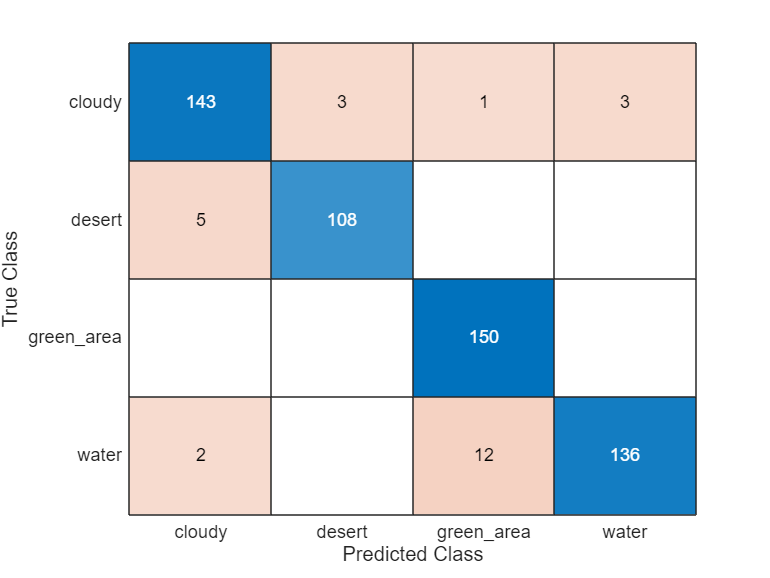

figure
confusionchart(true_labels, predicted_labels)

Most often network confuse green area with water (very similar looking classes)

Testing network on a image of hurricane out of curiosity if it will classify it as cloudy, even though it has been not trained on hurricane images 

test_folder = "";
imds_hurricane = imageDatastore(test_folder, ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames");

predicted_hurricane_labels = minibatchpredict(net, imds_hurricane);
predicted_hurricane_labels = scores2label(predicted_hurricane_labels,classNames);
pred_1 = string(predicted_hurricane_labels(1));
pred_2 = string(predicted_hurricane_labels(2));
img_1 = readimage(imds_hurricane, 1);
img_2 = readimage(imds_hurricane, 2);

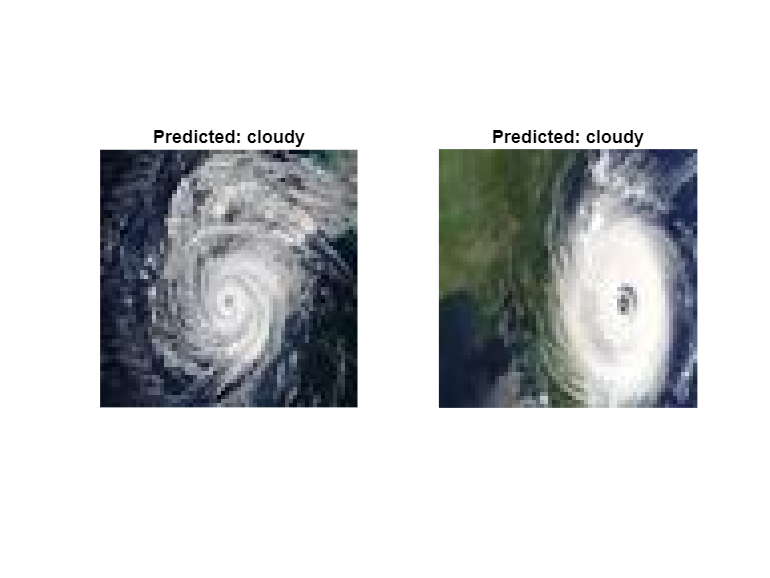

figure;
subplot(1,2,1);
imshow(img_1, 'InitialMagnification','fit');
title(sprintf('Predicted: %s', pred_1));
subplot(1,2,2);
imshow(img_2, 'InitialMagnification','fit');
title(sprintf('Predicted: %s', pred_2));

Correct predictions:)

save net;
filename = 'matlab_net.onnx';
exportONNXNetwork(net, filename);